    
i = 0.2;
    name = append('Action b = ',sprintf('%3.1f',i) ,'.txt');
    data = readtable(name);
    chem1 = data{[1:7],"Var1"};
    chem2 = data{[8:13],"Var1"};
    rlaction = data{[1:7],"Var2"};
    claction = data{[8:13],"Var2"};
    kmax = data{:,"Var3"};
    SD1 = data{[1:7],"Var4"};
    SD2 = data{[8:13],"Var4"};
    disp(sum(kmax,"all")/11)

   20.1419



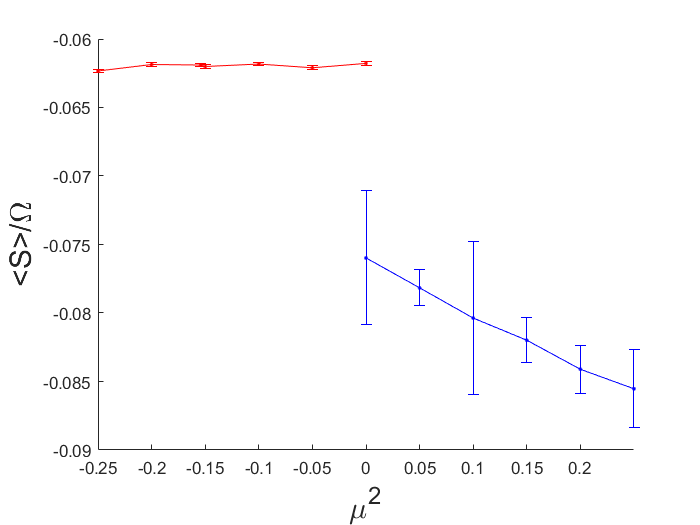

    
    hold on
    ylabel('<S>/\Omega','FontSize',18)
    xlabel('\mu^2','FontSize',18)
    errorbar(chem1,rlaction,SD1,'.red')
    plot(chem1,rlaction,'-red')
    errorbar(chem2,claction,SD2,'.blue')
    plot(chem2,claction,'-blue')